Open the dataset

close all; clear; clc

train = readtable("train.csv");

Transported 

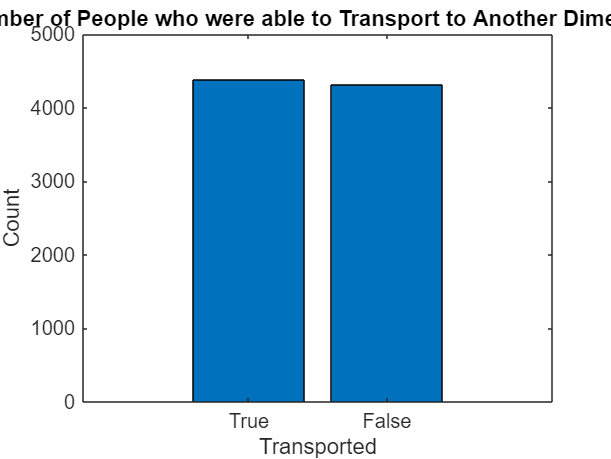

% Count how much transported and not transported
transported = table2array(train(:,"Transported")) == "True";
transported = sum(transported);
untransported = length(table2array(train(:,"Transported"))) - transported;

% Plotting
bar([transported untransported]);
set(gca, 'XTickLabel', {'True','False'});
xlabel("Transported");
ylabel("Count");
title("Number of People who were able to Transport to Another Dimension")

Age distribution and transportation chances

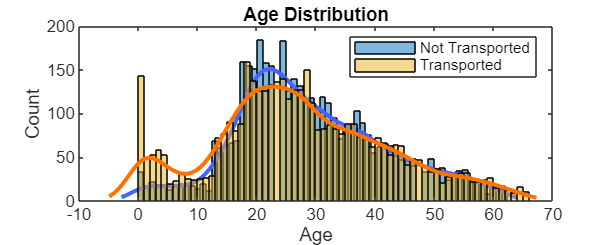

% Initialize the numbers
age = table2array(train(:,"Age"));
transported = table2array(train(:,"Transported"));

% Transported stats
ageTransported = age(transported == "True");
ageTransported = rmoutliers(ageTransported);
ageUntransported = age(transported == "False");
ageUntransported = rmoutliers(ageUntransported);
figure('Position', [100, 100, 1000, 400]);

% Plot Untransported
au = histfit(ageUntransported,[],'kernel');
au(1).FaceAlpha = 0.5;
au(2).Color = "#4662FF";
hold on;

% Plot Transported
at = histfit(ageTransported,[],'kernel');
at(1).FaceAlpha = 0.5;
at(2).Color = "#FF7200";

% Plot details
legend({'Not Transported', '', 'Transported'});
hold off;
xlabel('Age');
ylabel('Count');
title('Age Distribution');

Expenditures distribution

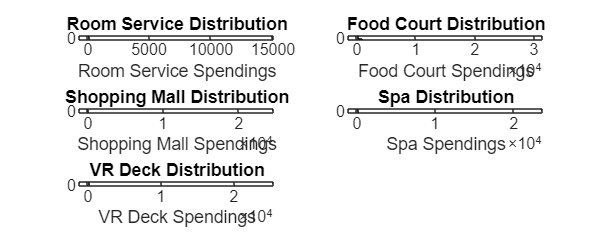

% Initialize the numbers
transported = table2array(train(:,"Transported"));
roomService = table2array(train(:,"RoomService"));
foodCourt = table2array(train(:,"FoodCourt"));
shoppingMall = table2array(train(:,"ShoppingMall"));
spa = table2array(train(:,"Spa"));
vrDeck = table2array(train(:,"VRDeck"));

% Plotting function
function plotting(feature, ttle, xlbl, figureNo)
    subplot(3,2,figureNo)

    % Plot 
    histogram(feature);

    % Plot details
    xlabel(xlbl);
    ylabel('Count');
    title(ttle);
end


% Plot
plotting(roomService, "Room Service Distribution", "Room Service Spendings", 1);
plotting(foodCourt, "Food Court Distribution", "Food Court Spendings", 2);
plotting(shoppingMall, "Shopping Mall Distribution", "Shopping Mall Spendings", 3);
plotting(spa, "Spa Distribution", "Spa Spendings", 4);
plotting(vrDeck, "VR Deck Distribution", "VR Deck Spendings", 5);

Expenditures

% Initialize the numbers
transported = table2array(train(:,"Transported"));
roomService = table2array(train(:,"RoomService"));
foodCourt = table2array(train(:,"FoodCourt"));
shoppingMall = table2array(train(:,"ShoppingMall"));
spa = table2array(train(:,"Spa"));
vrDeck = table2array(train(:,"VRDeck"));

% Plotting function
function transportPlotting(transported, feature, ttle, xlbl, figureNo, xlm)

    % Transported stats
    fTransported = feature(transported == "True");
    fUntransported = feature(transported == "False");
    subplot(3,2,figureNo)

    % Plot Untransported
    fu = histfit(fUntransported,[],'kernel');
    fu(1).FaceAlpha = 0.5;
    fu(2).Color = "#4662FF";
    hold on;

    % Plot Transported
    ft = histfit(fTransported,[],'kernel');
    ft(1).FaceAlpha = 0.5;
    ft(2).Color = "#FF7200";

    % Plot details
    legend({'Not Transported', '', 'Transported'});
    hold off;
    xlabel(xlbl);
    ylabel('Count');
    ylim([0 100]);
    xlim(xlm);
    title(ttle);
end


% Plot
transportPlotting(transported, roomService, "Room Service Distribution", "Room Service Spendings", 1, [0 15000]);
transportPlotting(transported, foodCourt, "Food Court Distribution", "Food Court Spendings", 2, [0 30000]);
transportPlotting(transported, shoppingMall, "Shopping Mall Distribution", "Shopping Mall Spendings", 3, [0 20000]);
transportPlotting(transported, spa, "Spa Distribution", "Spa Spendings", 4, [0 20000]);
transportPlotting(transported, vrDeck, "VR Deck Distribution", "VR Deck Spendings", 5, [0 20000]);

Categorical features

% Selected features
features = {'HomePlanet', 'CryoSleep', 'Destination', 'VIP'};

% Home Planet

% Plot a bar graph for each features, indicated whether they were
% transported or not
figure('Position', [100, 100, 1000, 1600]); 
for i  = 1:length(features)
    currentFeature = features{i};

    % Group data by feature and if transported
    [G, ID] = findgroups(train.(currentFeature), train.Transported); % Split into groups based on transported or not and feature status
    counts = splitapply(@numel, train.Transported, G); % Count the populations based on the split groups
    % Separate the transported or not into two different columns
    countsReshaped = zeros(length(counts)/2,length(counts)/2);
    countsReshaped(:,1) = counts(1:2:end); 
    countsReshaped(:,2) = counts(2:2:end);

    ID = unique(ID); % Make it unique so counts and ID have same column count

    % Plot
    subplot(4, 1, i);
    bar(ID,countsReshaped,"grouped")
    xlabel(currentFeature);
    ylabel('Count');
    title(currentFeature + " and if Transported");
    legend({'Not Transported', 'Transported'}, 'Location', 'northeast');
end

Qualitative features

% Preview qualitative features of the dataset
qualFeats = {'PassengerId', 'Cabin', 'Name'};
head(train(:,qualFeats))